依赖[统一实验分析作图v17.1.1](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

Reinforced final network

DataSet=TransferLearning.FullCalcium;

排序热图2

FinalCalcium=UniExp.NtatsCellReplenish(DataSet.QueryNTATS(UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'FinalRSPdHeat'),UniExp.Flags.dFdF0,1:24,UniExp.Flags.Median));

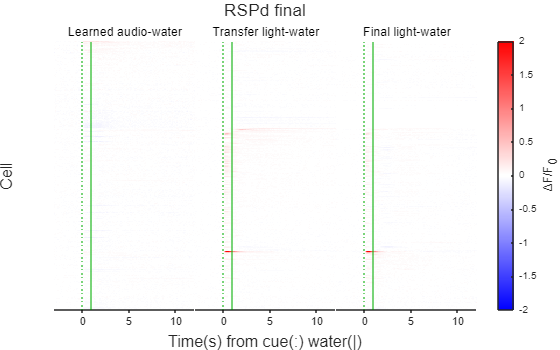

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
Data=FinalCalcium.NTATS{:,:,["Learned_audio_water","Transfer_light_water","Final_light_water"]};
%Data=Data(any(Data,2:3),:,:);
Layout=TransferLearning.AucGroupSortedHeatmap(Data,["Learned audio-water","Transfer light-water","Final light-water"],Colors,false);
title(Layout,'RSPd final');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('FinalRSPdHeat.svg'),'-dsvg');